clear all
syms x(t) y(t) theta(t) Fx(t) Fy(t) t m g L
F=[Fx(t);Fy(t)];
rG=[x(t);y(t)];
m=1;
L=2;
g=9.81;
%F=ma
eq1=m*diff(rG,t,2)==(F-m*g*[0;1]);
MFG=cross(-[rG;0],[F;0]);
%IG theta''=M
eq2=1/12*m*L^2*diff(theta,t,2) ==MFG(3);
%Keep the thing in place. 
eq3=rG==L/2*[sin(theta);-cos(theta)];


Found multiple suitable values for Dxt:
 	0.866025
	-0.866025
Arbitrarily selecting the first one.
Found multiple suitable values for Dyt:
 	0.500000
	0.500000
Arbitrarily selecting the first one.
Found multiple suitable values for theta:
 	0.523599
	2.617994
Arbitrarily selecting the first one.
Found multiple suitable values for y:
 	-0.866025
	0.866025
Arbitrarily selecting the first one.
Initial Conditions:
Y0/YP0:
x: 0.500000 xt:0.866025
y: -0.866025 yt:0.500000
theta: 0.523599 thetat:1.000000
Fx: -3.685891 Fxt:0.000000
Fy: 8.836650 Fyt:0.000000
Dxt: 0.866025 Dxtt:-3.685891
Dyt: 0.500000 Dytt:-0.973350
Dthetat: 1.000000 Dthetatt:-3.678750


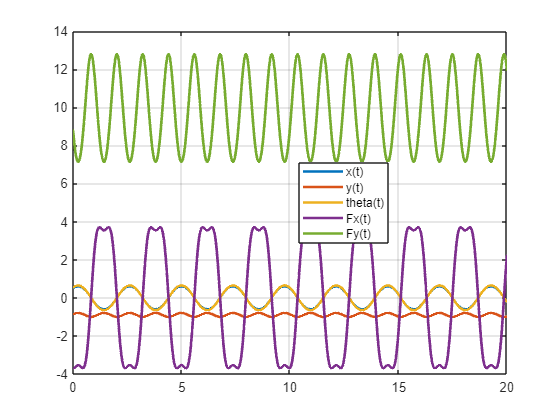

%Solve the system of equations using the purely numerical mechanics DAE
%solver. The initial conditions can be given in a variety of forms. 
soln=mechanicsAsDAE([eq1;eq2],[eq3],[],[x,y,theta,Fx,Fy],0,20,[x==0.5,diff(theta)==1]);

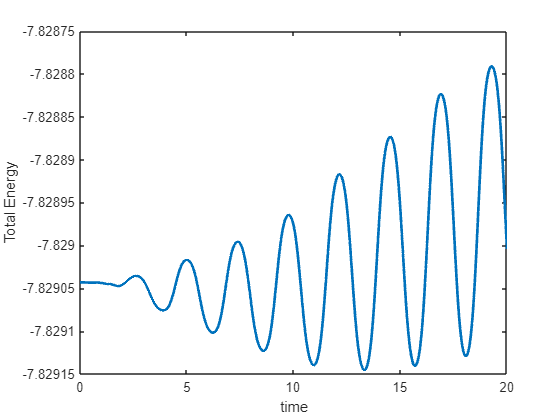

%The numerical solution has one field for each unknown.  Here we calculate
%the total energy of the system over time to see if it is holding steady.
%Not bad. 
KineticEnergy=1/2*m*(soln.Dxt.^2+soln.Dyt.^2) + 1/2*1/12*m*L^2*soln.Dthetat.^2;
PotentialEnergy=m*soln.y*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

%Now approach the same problem analytically.  Try to turn your system of
%DAE into a "first" system of pure ODE (the classic formulation) and then a
%series of "post-processing" equations. 
[DEs,PP] = analyzeSystem([eq1;eq2],eq3,[],[x,y,Fx,Fy,theta],[theta,diff(theta)])

There are 9 equations, and 5 unknown time-varying functions.
The algebraic (force) functions are:
Fx(t)
Fy(t)

Adding in all constraints, and counting pure symbols (so that x, Dxt, Dxtt count as 3 symbols) I get:
equations: 9
symbols:11
free parameters: 2.

Expected number of state variables: 2



$$DEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{2943\,\sin\left(\theta \left(t\right)\right)}{400}$$

$$PP = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\sigma_{2}\\ \frac{\partial }{\partial t}y\left(t\right)=\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\sigma_{3}+\sigma_{1}-\frac{2943}{400}\\ \mathrm{Fx}\left(t\right)=\sigma_{2}\\ \mathrm{Fy}\left(t\right)=\sigma_{3}+\sigma_{1}+\frac{981}{400}\\ x\left(t\right)=\sin\left(\theta \left(t\right)\right)\\ y\left(t\right)=-\cos\left(\theta \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2943\,{\cos\left(\theta \left(t\right)\right)}^{2}}{400}\\ \sigma_{2}=-\sin\left(\theta \left(t\right)\right)\,\sigma_{4}-\frac{2943\,\sin\left(2\,\theta \left(t\right)\right)}{800}\\ \sigma_{3}=\cos\left(\theta \left(t\right)\right)\,\sigma_{4}\\ \sigma_{4}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

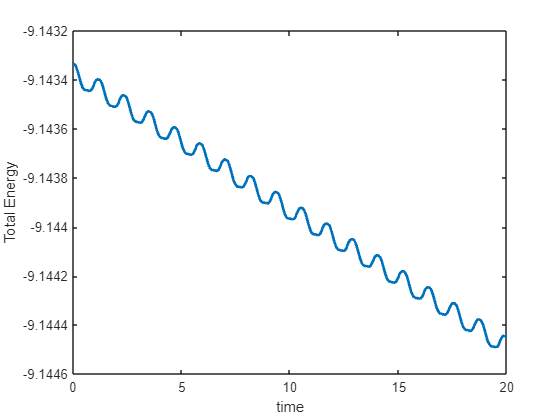

%Take the pure ODE system that you got above, and time step it using ODE
%23s.  You can also try to solve the problem above using, e.g., the build
%in dsolve command. 


soln=timeStepODESystem(DEs,[theta],{theta==0,diff(theta)==1},[0,20],PP);

%Solution has a field for each unknown function now.  Do as you will with
%them. 
KineticEnergy=1/2*m*(soln.Dxt.^2+soln.Dyt.^2)+1/2*1/12*m*L^2*soln.Dthetat.^2;
PotentialEnergy=m*soln.y*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')